# Aula 6 - Compensador de Avanço/Atraso

## 1) Compensador de Avanço / PD

a) Usando da técnica de L.R, projetar $K_p$ e $T_d$  para que o fator de amortecimento dos polos em Malha Fechada do sistema de controle abaixo seja 0,7 e a frequência natural em malha fechada seja  $\omega_n =0\ldotp 5\;\textrm{rad}$/s

clear
close all

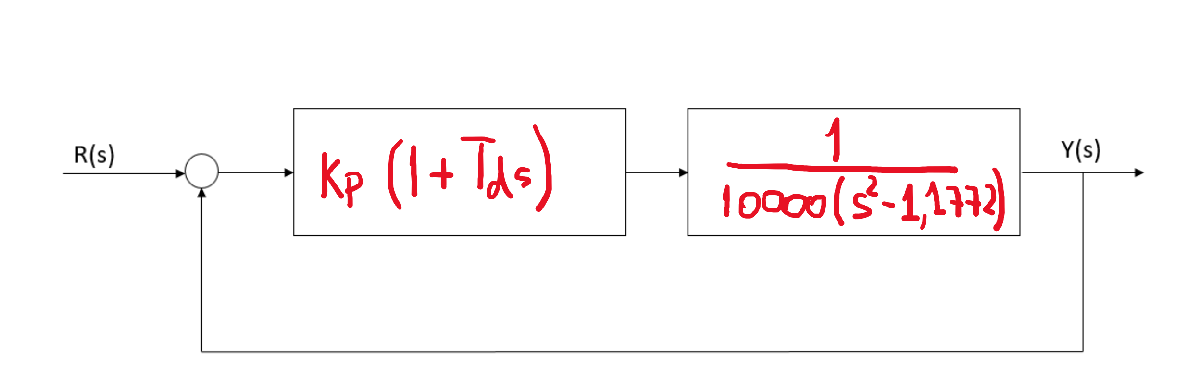

Fórmula geral do compensador de avanço: $G_c=K_c\frac{1+sT}{1+s\alpha T}$.

Adiciona um zero e um pólo e o zero deve ficar a direita do pólo($\alpha<1$). 

Caso especial, controlador PD: $G_c=K_p(1+T_ds)$, $\alpha=0$.

Adiciona somente um zero em $s=-\frac{1}{T_d}$

1º) Pólo desejado


$$s=-\zeta\omega_n\pm j\omega_n\sqrt{1-\zeta^2}$$


zeta=0.7;
omega_n=0.5;
s=-zeta*omega_n+j*omega_n*sqrt(1-zeta^2)

s = -0.3500 + 0.3571i

2º) LR da planta

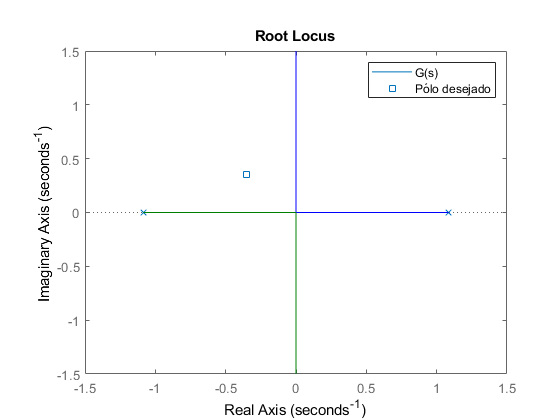

G=1e-4*tf(1,[1,0,-1.1772]);
rlocus(G)
hold on
scatter(real(s),imag(s),'s')
hold off
legend('G(s)','Pólo desejado')

3º)Encontrar a posição do zero pela codição de fase.

Condição de Fase:

$\sum_m \phi_i - \sum_n \theta_j =180º \pm k360º$ , para $k$ inteiro.

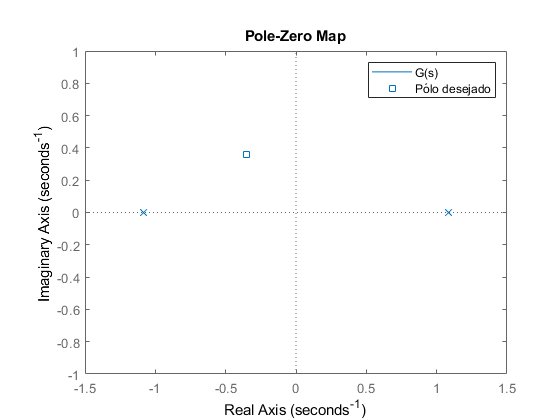

pzmap(G)
hold on
scatter(real(s),imag(s),'s')
hold off
legend('G(s)','Pólo desejado')

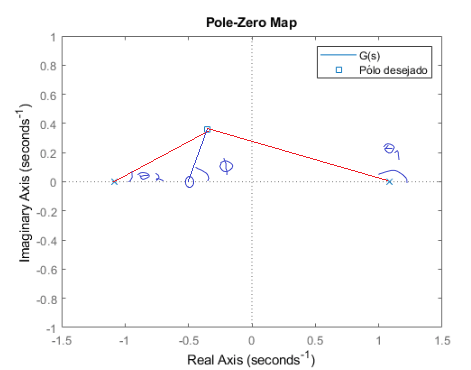

p=pole(G);
theta1=180-atand(imag(s)/(p(1)-real(s)))

theta1 = 166.0267

theta2=atand(imag(s)/(real(s)-p(2)))

theta2 = 25.9114

phi=-180+theta1+theta2

phi = 11.9381

x=imag(s)/tand(phi)

x = 1.6889

z=real(s)-x

z = -2.0389

Td=-1/z

Td = 0.4905

Gc=tf([Td,1],1)

Gc =
 
  0.4905 s + 1
 
Continuous-time transfer function.



4º) Encontrar $K_p$ pela condição de módulo.

Condição de módulo:


$$\left| K_p G_c G \right|_{s=s_{desejado}} =1$$


Kp=1/abs(1+Td*s)*1e4*abs(s^2-1.1772)

Kp = 14272

b) Simular o sistema a uma entrada em degrau da referência usando Matlab / Python / Scilab / Octave e mostre que a resposta obtida está coerente. Coloque os gráficos obtidos.

sys=feedback(Kp*Gc*G,1);
damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.50e-01 + 3.57e-01i     7.00e-01       5.00e-01         2.86e+00    
 -3.50e-01 - 3.57e-01i     7.00e-01       5.00e-01         2.86e+00    


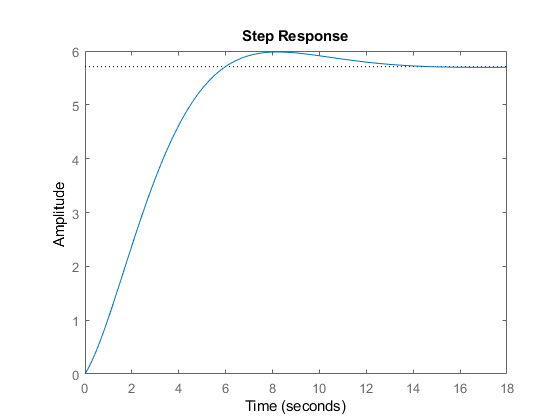

step(sys)

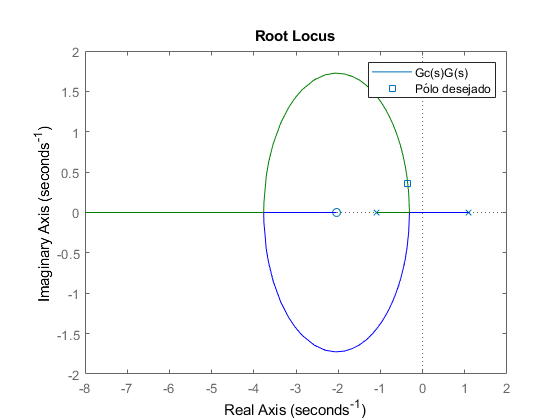

rlocus(Gc*G)
hold on
scatter(real(s),imag(s),'s')
hold off
legend('Gc(s)G(s)','Pólo desejado')

## 2) Compensador de Atraso

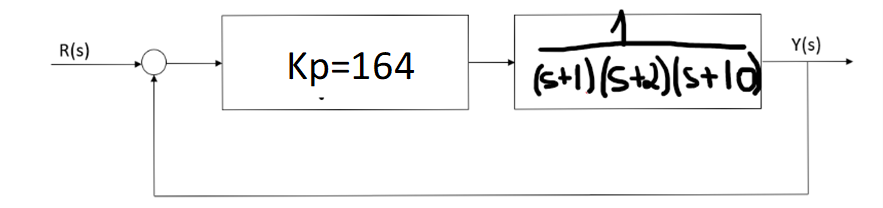

a)Verifique as características de resposta transitória (amortecimento e frequência natural) para o sistema de controle acima, com realimentação unitária.

clear
close all
den=conv(conv([1,1],[1,2]),[1,10]);
G=tf(1,den);
Kp=164;
damp(feedback(Kp*G,1))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.96e-01 + 3.92e+00i     1.75e-01       3.98e+00         1.44e+00    
 -6.96e-01 - 3.92e+00i     1.75e-01       3.98e+00         1.44e+00    
 -1.16e+01                 1.00e+00       1.16e+01         8.61e-02    


b) Projeto um compensador de atraso que faça com que o erro em regime para uma entrada em degrau seja reduzido em 10, mantendo as características de resposta transitória.

Fórmula geral do compensador de atraso: $G_c=K_c\frac{1+sT}{1+s\beta T}$.

Adiciona um zero e um pólo e o zero deve ficar a esquerda do pólo($\beta>1$). Como o objetivo do controlador de atraso é não alterar muito o lugar das raízes do sistema, o pólo e o zero adicionados devem estar próximos o suficiente para $|\theta-\phi|\leq5º$. Além disso, $\frac{Kc}{\beta}=1$.

Para entrada degrau:

seja $K=\lim_{s\rightarrow 0}G(s)=\lim_{s\rightarrow 0}\frac{164}{(s+1)(s+2)(s+10)}=\frac{164}{1\times2\times10}=8.2$

ess=1/(1+8.2)

ess = 0.1087


$$e_{ss}=\frac{1}{1+K}=\frac{1}{1+8.2}=0.1087$$



$$e_{ss}^{desejado}=\frac{e_{ss}}{10}=0.01087=\frac{1}{1+K^{desejado}}$$



$$K^{desejado}=\frac{10}{e_{ss}}-1$$


K_desejado=10/ess-1

K_desejado = 91.0000


$$K^{desejado}=\lim_{s\rightarrow 0}G_c(s)*G(s)=K_c *8.2$$


Kc=K_desejado/8.2

Kc = 11.0976


$$K_c=\beta=11.1$$


Para manter as características de resposta transitósia, devemos manter como pólo dominante $s=-0.696+j3.97$.

Fazendo T=10s temos:

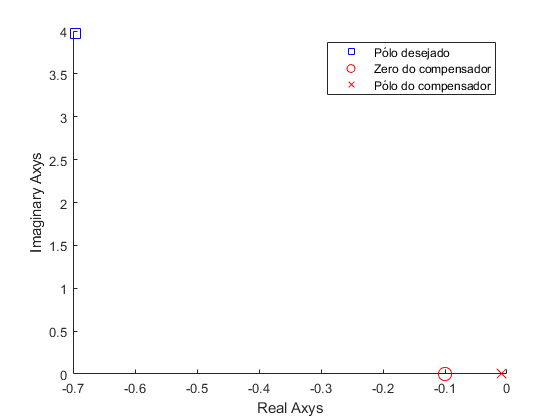

s=-0.696+j*3.97;
T=10;
beta=11.1;
Kc=11.1;
z=-1/T;
p=-1/(beta*T);
sz=100; %tamanho do scatter
scatter(real(s),imag(s),sz,'s','MarkerEdgeColor','Blue')
hold on
scatter(z,0,sz,'MarkerEdgeColor','Red')
scatter(p,0,sz,'x','MarkerEdgeColor','Red')
legend('Pólo desejado','Zero do compensador','Pólo do compensador')
xlabel('Real Axys')
ylabel('Imaginary Axys')
hold off

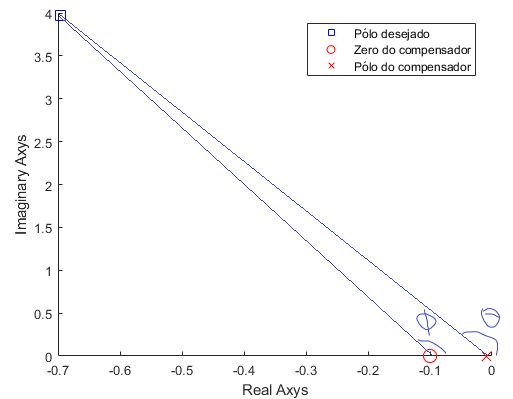

theta=180-atand(imag(s)/(p-real(s)))

theta = 99.8176

phi=180-atand(imag(s)/(z-real(s)))

phi = 98.5378

LogicalStr = {'Não, escolhe outro valor de T.', 'Sim, valor de T aceito.'};
fprintf(' Módulo de (Phi - Theta) é menor que 5 graus? \n %s',LogicalStr{(abs(theta-phi)<5)+1})

 Módulo de (Phi - Theta) é menor que 5 graus? 
 Sim, valor de T aceito.

Então,

 $G_c(s)=K_c\frac{1+sT}{1+s\beta T}=11.1\frac{1+10s}{1+111s}$.

c) Simular o sistema a uma entrada em degrau da referência usando Matlab / Python / Scilab / Octave e mostre que a resposta obtida está coerente. Coloque os gráficos obtidos.

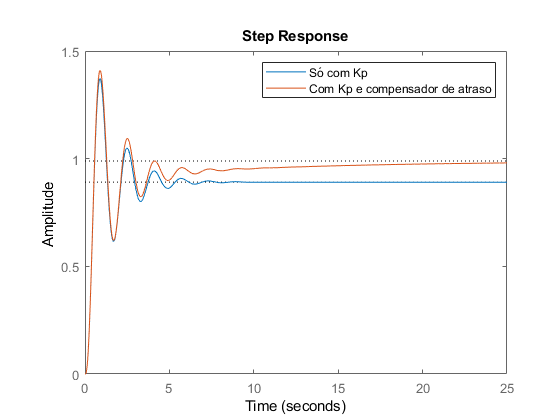

Gc=Kc*tf([T,1],[T*beta,1]);
sysG=feedback(Kp*G,1);
sysGc=feedback(Gc*Kp*G,1);
step(sysG)
hold on
step(sysGc)
hold off
legend('Só com Kp', 'Com Kp e compensador de atraso')

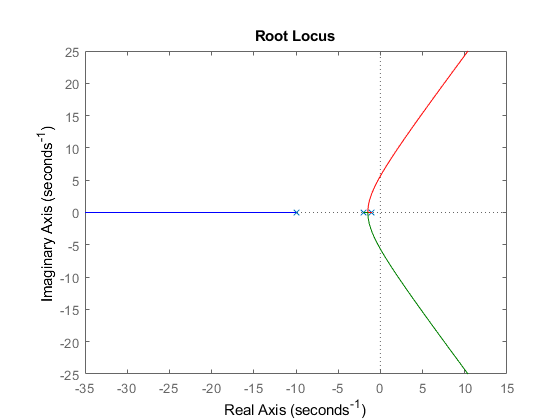

rlocus(Kp*G)

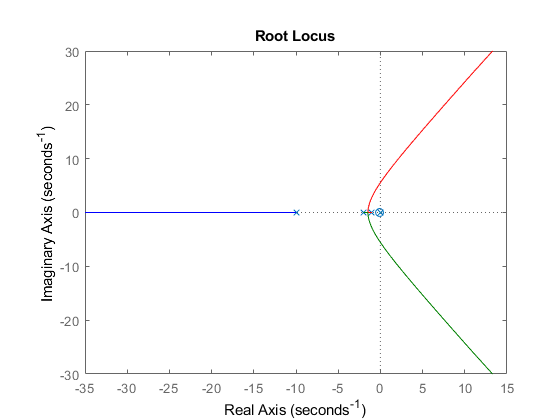

rlocus(Gc*Kp*G)

Gc*Kp*G

ans =
 
                18204 s + 1820
  -------------------------------------------
  111 s^4 + 1444 s^3 + 3565 s^2 + 2252 s + 20
 
Continuous-time transfer function.



Kgc=1820/20 %limite da função de transferência de malha aberta com o compensador

Kgc = 91

essGc=1/(1+Kgc) %erro em estado estacionário com compensador

essGc = 0.0109

ess/essGc %erro sem compensador dividido pelo erro com compensador

ans = 10.0000